clear variables;
addPath;

%tempo reduction param
para.kF = 20;
para.redL = 5;
para.reduct = false;

%kernel setting
para.kernel = .2;

%ACA param
para.nMi = 5;
para.nMa = 10;
para.ini='r';
para.k=8;
para.nIni=1;

%HACA param
para.haca = false;
if para.haca 
    para2 = para;
    para2.nMi = 3;
    para2.nMa = 8;
    para2.k=4;
    para2.nIni=10;
    paraH = [para para2];
end

%output path
out_path = './output/6/';
mkdir(out_path);


%select cluster num
% sel_num = 2;

## Single mice feat CSV

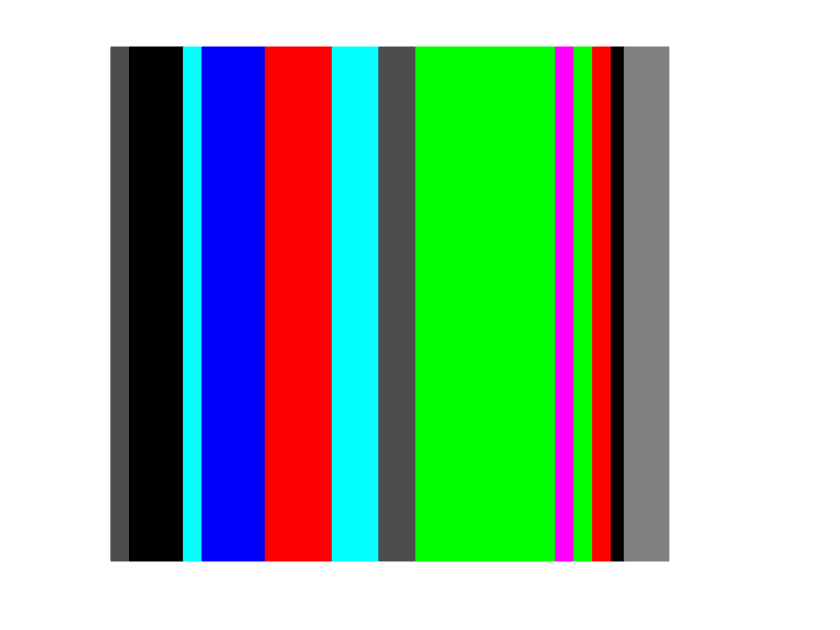

path = 'C:\Users\x\Desktop\vid_top\0test\short_feat_AE.csv';
X = table2array(readtable(path))';
% offset to nonnegative
X = X+repmat(min(X,[],2),1,size(X,2));
K = conKnl(conDist(X, X),para.kernel);
seg = segIniR(K, para);
if para.haca
    segResult = segHaca(K, paraH, seg);
else
    segResult = segAca(K, para, seg);
end
clf;
showSegBar(segResult.s, segResult.G, [1 1 1 1], 0, -1, ' ');

videoLabel(segResult.s, segResult.G, 'C:\Users\x\Desktop\vid_top\0test\short.avi', 'C:\Users\x\Desktop\vid_top\0test\short_label.avi', -1);

## PSR data

path = '../feat/PSR/1.csv';
X = table2array(readtable(path))';
y = X(16,:);
X(16,:) = [];

% ground truth
yG = onehotencode(y, 1,'ClassNames', unique(y));
GTs = 1;
GTG = yG(:,1);
pre = y(1);
for i =2:size(y,2)
    if pre~=y(i)
        GTs = [GTs i];
        GTG = [GTG yG(:,i)];
    end
    pre = y(i);
end
GTs = [GTs size(y,2)+1];


K = conKnl(conDist(X, X),para.kernel);
seg = segIniR(K, para);
if para.haca
    segResult = segHaca(K, paraH, seg);
else
    segResult = segAca(K, para, seg);
end

clf;
showSegBar(segResult.s, segResult.G, [1 2 1 1], 1, -1, 'ACA');
showSegBar(GTs, GTG, [1 2 1 2], 1, -1, 'GT');

## Plot BSOiD cluster

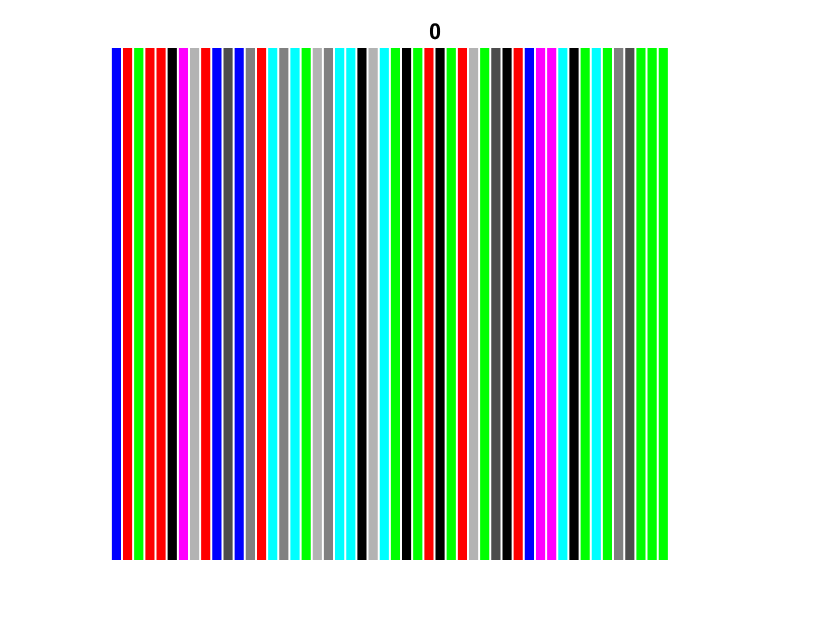

raw = readtable('C:\Users\x\Desktop\vid_top\0test\bsoid_label.csv');
y = table2array(raw(:,1))';
y = y(1,17:66);
GTG = onehotencode(y, 1,'ClassNames', unique(y));
GTs = 1;
for i =1:size(GTG,2)
    GTs = [GTs i*6+1];
end
showSegBar(GTs, GTG, [1 1 1 1], 1, -1, '0');
videoLabel(GTs, GTG, 'C:\Users\x\Desktop\vid_top\0test\short.avi', 'C:\Users\x\Desktop\vid_top\0test\short_bsoid_label.avi', -1);

## plot BSOiD RF prediction

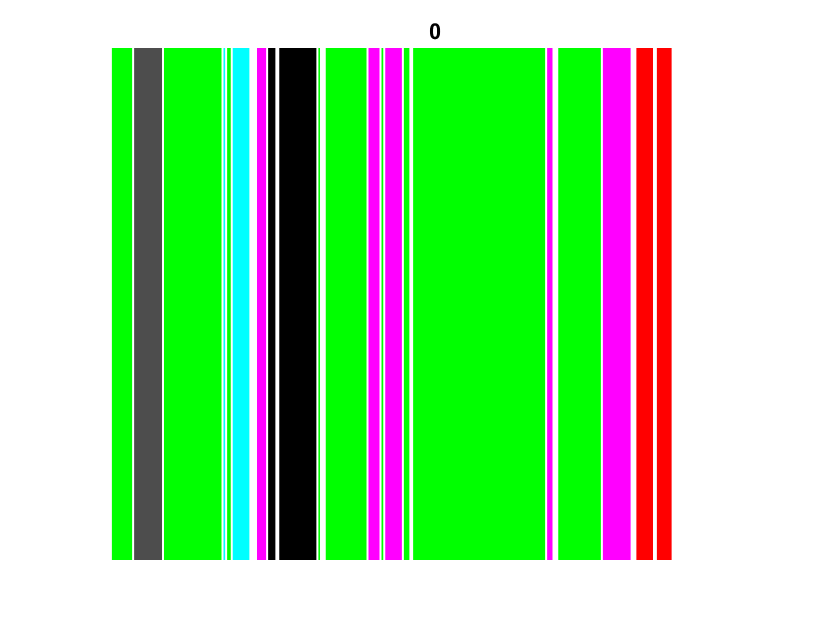

raw = readtable('C:\Users\x\Desktop\B-soid\B-SOID\test3\control\BSOID\Sep-21-2022labels_pose_60Hzshort.csv');
y = table2array(raw(:,2))';
yG = onehotencode(y, 1,'ClassNames', unique(y));
GTs = 1;
GTG = yG(:,1);
pre = y(1);
for i =2:size(y,2)
    if pre~=y(i)
        GTs = [GTs i];
        GTG = [GTG yG(:,i)];
    end
    pre = y(i);
end
GTs = [GTs size(y,2)+1];
showSegBar(GTs, GTG, [1 1 1 1], 1, -1, '0');
videoLabel(GTs, GTG, 'C:\Users\x\Desktop\vid_top\0test\short.avi', 'C:\Users\x\Desktop\vid_top\0test\short_bsoid_label.avi', -1);